clear; clc; close all;

nfft = 128;
M = 32;
ofdm_symbols = 50;
snr = 23;
%multipath = [1 0.1 0.3 0.3];
multipath = [1 0.2];
%multipath = 1;

cp_len = nfft/4;
rep = 4;
pilot_index = 1:rep:nfft;


**Transmit:**

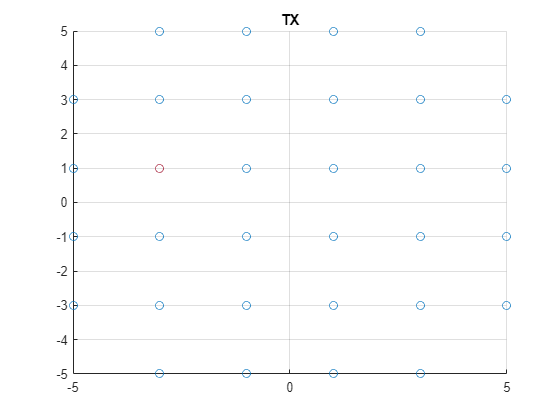

rng default
pilot_data = randsrc(length(pilot_index),ofdm_symbols,0:M-1);
P = qammod(pilot_data,M);
rng default
tx_data = randsrc(nfft,ofdm_symbols,0:M-1);
X = qammod(tx_data,M);
tx_data(pilot_index,:) = [];
X(pilot_index,:) = P;

figure(),scatter(real(X),imag(X)),title('TX'),grid on


x_pre_cp = ifft(X,nfft);
cp = x_pre_cp(nfft-cp_len+1:end,:);
x = vertcat(cp,x_pre_cp);

**Channel:**

x_channel = awgn(x,snr,'measured');
x_channel = exp(-1i*pi/4)*x_channel;

x_channel = filter(multipath,1,x_channel);

**Demodulate:**

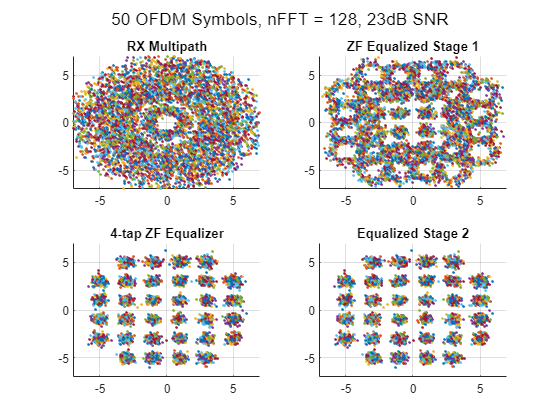

x_rx = x_channel(cp_len+1:end,:);
phase_offset = exp(-1j*0.6*[1:ofdm_symbols]);
x_rx = x_rx .* phase_offset;
X_RX = fft(x_rx,nfft);

P_RX = X_RX(pilot_index,:);

H = conj(P_RX) ./ conj(P);
H_P = mean(H);

Z_EQ = X_RX;
Z_EQ2 = X_RX;Z_EQ3 = X_RX;
% ZF with 1 interpolation point
for i=1:ofdm_symbols
    Z_EQ(:,i) = X_RX(:,i) * exp(1j*angle(H_P(i)));
end
P_RX2 = Z_EQ(pilot_index,:);
H2 = conj(P_RX2) ./ conj(P);
H_ZF = conj(H2) ./ abs(H2 .* H2);
num_taps = 4;
% Stage 1 4-tap ZF equalizer
for i = 1:ofdm_symbols
    for k = 1:length(pilot_index)
        index = ((rep)*(k-1)+1:(rep)*k);
        if (k~=length(pilot_index)) && (i~=ofdm_symbols-2) && (i~=ofdm_symbols-1) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1) H_ZF(k,i+2) H_ZF(k+1,i+2) H_ZF(k,i+3) H_ZF(k+1,i+3)]);
        elseif (k~=length(pilot_index)) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1)]);
        elseif (k~=length(pilot_index))
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i)]);
        end
        Z_EQ2(index,i) = Z_EQ(index,i) .* conj(H_tmp);
    end
end
Z_EQ3 = Z_EQ2;
% for i = 1:ofdm_symbols
%     index = ((rep)*(k-1)+1:(rep)*k);
%     Z_EQ2(index,i) = Z_EQ(index,i) .* conj(H2_ZF(k,i));
% end

% X_RX(pilot_index,:) = [];
% Z_EQ(pilot_index,:) = [];
% Z_EQ2(pilot_index,:) = [];
% Z_EQ3(pilot_index,:) = [];
% 
% no_eq = qamdemod(X_RX,M);
% zf_eq = qamdemod(Z_EQ,M);
% zf_eq_1_interp = qamdemod(Z_EQ2,M);
% zf_eq_1_interp_4_tap = qamdemod(Z_EQ3,M);
% 
% no_eq_ser = symerr(tx_data,no_eq)/numel(tx_data);
% zf_eq_ser = symerr(tx_data,zf_eq)/numel(tx_data);
% zf_eq_1_interp_ser = symerr(tx_data,zf_eq_1_interp)/numel(tx_data);
% zf_eq_1_interp_4_tap = symerr(tx_data,zf_eq_1_interp_4_tap)/numel(tx_data);
% 
% X(pilot_index,:) = [];
% evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
% [no_eq_evm,no_eq_pk] = evm(X,X_RX);
% [zf_eq_evm,zf_eq_pk] = evm(X,Z_EQ) ;
% [zf_eq_1_interp_evm,zf_eq_1_interp_pk] = evm(X,Z_EQ2);
% [zf_eq_1_interp_4_tap_evm,zf_eq_1_interp_4_tap_pk] = evm(X,Z_EQ3);
% 
% Equalization = ["No Equalization";"ZF";"Interpolated ZF";"4-Tap Interpolated ZF"];
% SER = [no_eq_ser;zf_eq_ser;zf_eq_1_interp_ser;zf_eq_1_interp_4_tap];
% AverageEVM = [no_eq_evm;zf_eq_evm;zf_eq_1_interp_evm;zf_eq_1_interp_4_tap_evm];
% PeakEvm = [no_eq_pk;zf_eq_pk;zf_eq_1_interp_pk;zf_eq_1_interp_4_tap_pk];
% 
% table(Equalization,SER,AverageEVM,PeakEvm)

y_lim = [-7 7]; x_lim = [-7 7];
%y_lim = [-9 9]; x_lim = [-9 9];
figure(),subplot(2,2,1),scatter(real(X_RX),imag(X_RX),'.','lineWidth',2),grid on,title('RX Multipath'),xlim(x_lim),ylim(y_lim)
subplot(2,2,2),scatter(real(Z_EQ),imag(Z_EQ),'.','lineWidth',2),grid on,title('ZF Equalized Stage 1'),xlim(x_lim),ylim(y_lim)
subplot(2,2,3),scatter(real(Z_EQ2),imag(Z_EQ2),'.','lineWidth',2),grid on,title('4-tap ZF Equalizer'),xlim(x_lim),ylim(y_lim)
subplot(2,2,4),scatter(real(Z_EQ3),imag(Z_EQ3),'.','lineWidth',2),grid on,title('Equalized Stage 2'),xlim(x_lim),ylim(y_lim)
sgtitle([num2str(ofdm_symbols),' OFDM Symbols, nFFT = ',num2str(nfft),', ',num2str(snr),'dB SNR'])

% Plot EVM vs Subcarriers 
evm = comm.EVM(AveragingDimensions=2);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ3);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:nfft-cp_len,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,2),bar(1:nfft-cp_len,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(1:nfft-cp_len,zf_eq_1_interp_evm),title('EVM ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,4),bar(1:nfft-cp_len,zf_eq_1_interp_4_tap_evm),title('EVM 4-tap ZF 1 Interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
sgtitle(['EVM Averaged Across Sub-Carriers ',num2str(snr),'dB SNR'])
% Plot EVM vs OFDM Symbols
evm = comm.EVM(AveragingDimensions=1);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ3);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:ofdm_symbols,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,2),bar(1:ofdm_symbols,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(1:ofdm_symbols,zf_eq_1_interp_evm),title('EVM ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,4),bar(1:ofdm_symbols,zf_eq_1_interp_4_tap_evm),title('EVM 4-tap ZF 1 Interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
sgtitle(['EVM Averaged Across OFDM Symbols ',num2str(snr),'dB SNR'])
% figure(),subplot(2,2,1),s = surf(abs(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
% colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Abs(H)')
% subplot(2,2,2),s = surf(angle(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
% colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Angle(H)')
% subplot(2,2,3),s = surf(real(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
% colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Real(H)')
% subplot(2,2,4),s = surf(imag(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
% colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Imag(H)')
